# WINDSURFER/NORA3, hindcast 3km hourly instantaneous wave fields

The present script downloads and process automatically the WINDSURFER/NORA3 wave field hindcast with a  time resolution of1 h and a spatial resolution of ca. 3 km. The data set covers the period from 1993 to 2020. The wave hindcast are obtained with WAM wave model version cycle 4.7.0. The Norwegian Meteorological Instituteprovided the data freely. These are available on their Thredds server [1]. The documentation is contained into the netcdf files that are read through the opendap frawmweork.

The outputs extracted in the present example are 

- the mean wind speed at 10 m above sea level (asl) **ff**

- the wind direction at 10 m asl **dd**

- The surface friction velocity **FV**

- The drag coefficient **DC**

- the total significant wave height** hs**

- The Total peak period** tp**

- The Total mean wave direction** thq**

- the wind sea significant wave height  **hs_sea**

- The wind sea peak period **tp_sea**

- The wind sea mean wave direction **thq_sea**

- the swell significant wave height hs**_swell**

- The swell peak period **tp_swell**

- The swell mean wave direction **thq_swell**

- the sea-ice area fraction **SIC**

- the sea-ice thickness **SIT**

- the water depth (sea floor depth below sea level) **model_depth**

There exist more variables that can be extracted, but these are beyond the scope of this example

[1] https://thredds.met.no/thredds

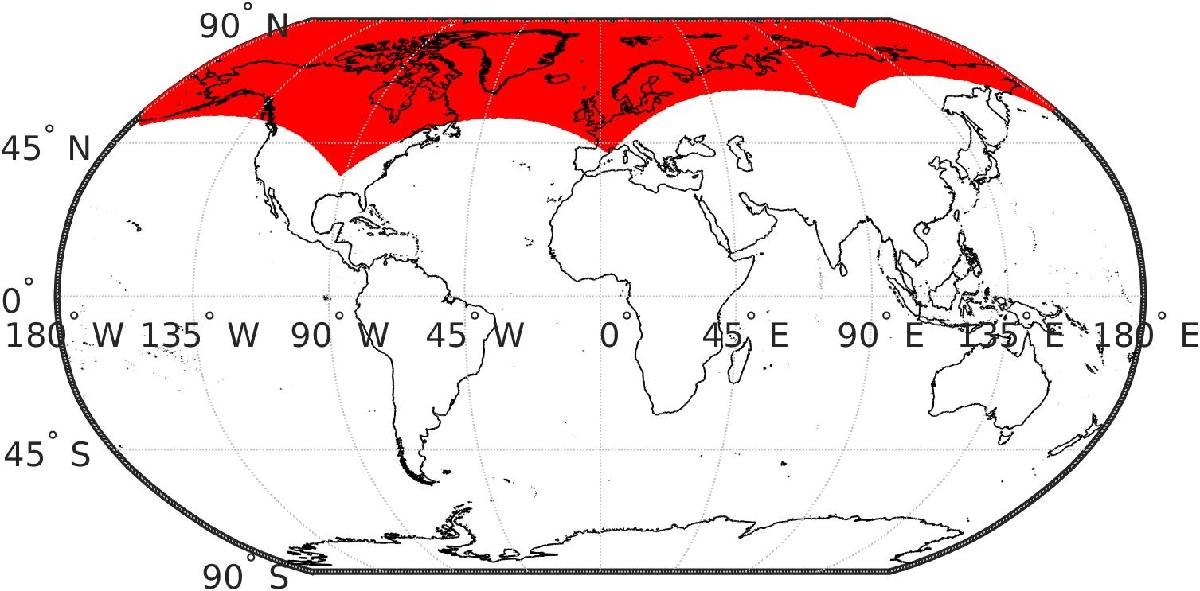

Fig 1: The domain covered by the computational grid covers the north hemisphere up to the arctic region

## Initialisation


clearvars;close all;clc; 
targetDate = datetime(2017,12,08); % extract some data from storm Aina
resolution = 0.06; % resolution for latitude and longitude in degrees
targetLat = [59 63]; % target latitude (between 52 and 74)
targetLon = [1 8];  % target longitude (between -11 and 42)
N = numel(targetDate); % number of samples (here only one)
[lon,lat] = meshgrid(targetLon(1):resolution:targetLon(end),targetLat(1):resolution:targetLat(end));
[Nlat,Nlon]=size(lat);

% select the output (cf. documentation from the netcdf files to see what
% they represent)
output = {'ff','dd','FV','DC','hs','tp',...
    'hs_sea','tp_sea','hs_swell','tp_swell',...
    'thq','thq_sea','thq_swell','SIC','SIT','model_depth'};

% their unit is here
unit = {'(m/s)','(deg)','(m/s)','(-)','(m)','(s)','(m)','(s)','(m)','(s)',...
    '(deg)','(deg)','(deg)','(-)','(m)','(m)'};

## Main loop

% Give one day of data in each loop
time = NaT(1,N);
clear data
for ii=1:N
    tic
    targetYear = num2str(year(targetDate(ii)));
    targetMonth = num2str(month(targetDate(ii)));
    targetDay = num2str(day(targetDate(ii)));    
    [data(ii)] = windsurfer(targetLat,targetLon,targetYear,targetMonth,targetDay,output,resolution);
    toc
end

Elapsed time is 164.497480 seconds.


## Visualization of the data extracted

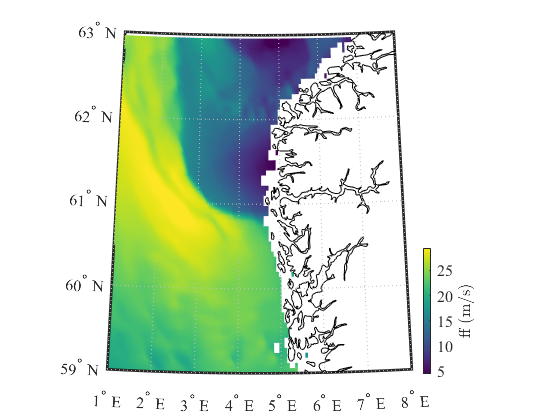

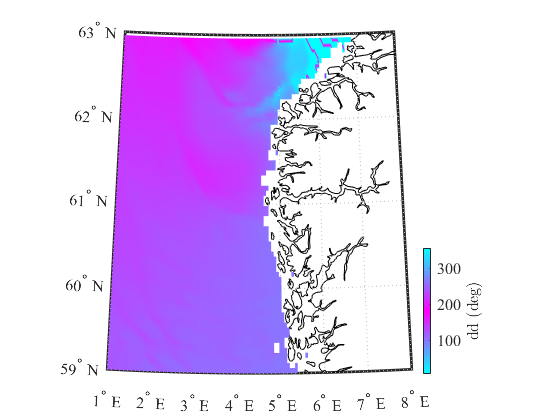

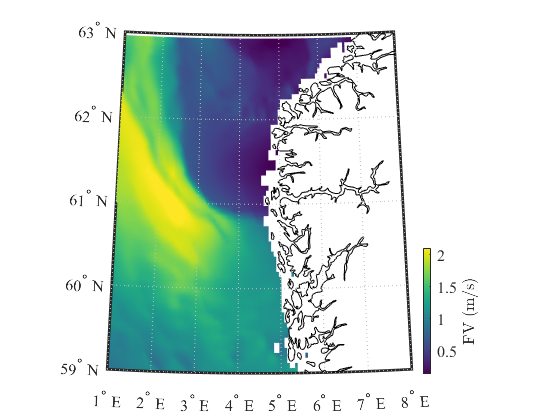

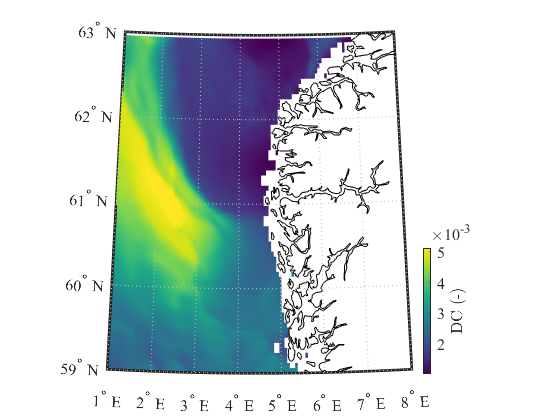

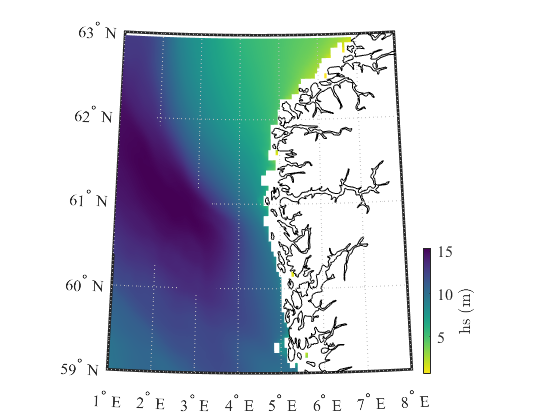

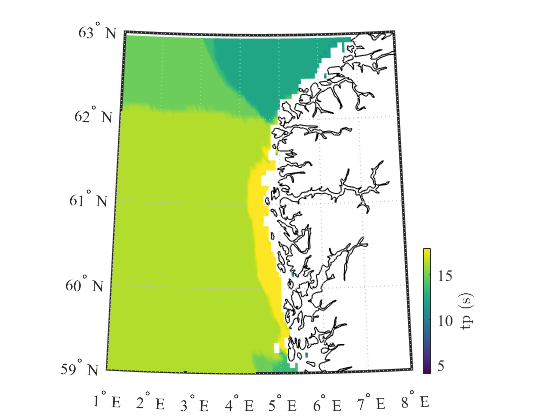

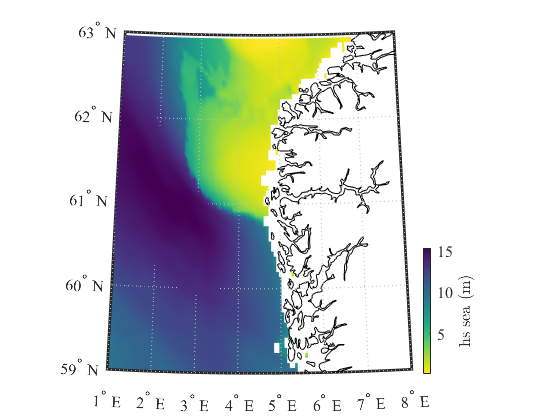

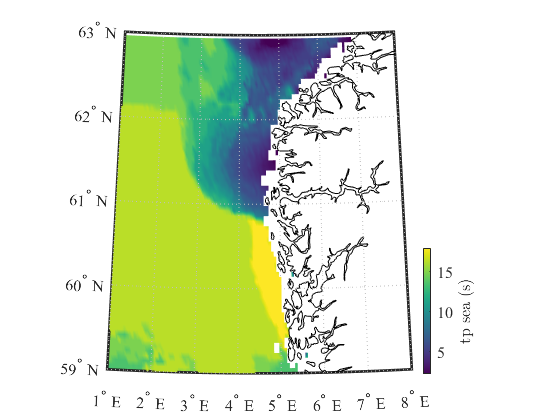

load('world.mat'); % Load borders of countries
ii = 1;
Noutput = numel(output);

clf;close all;

for pp=1:Noutput
        Z = squeeze(data.(lower(output{pp}))(1,:,:)); 
   
    figure
    if  license('test','MAP_Toolbox')
        worldmap(targetLat,targetLon)
        geoshow(data.lat,data.lon,Z, 'DisplayType','surface')
        hold on
        g = geoshow(world.lat,world.lon,'DisplayType','Line');
        g.Color = [0 0 0];
    else
        imagesc(data.lon(:,1),data.lat(1,:),Z');axis xy
        hold on
        plot(world.lon,world.lat,'k')
        pbaspect([1 1 1])
    end
    hold on
    if exist('viridis.m')==2
        if strcmpi(unit{pp},'(m/s)')|strcmpi(unit{pp},'(s)')|strcmpi(unit{pp},'(-)')
            colormap('viridis')
        elseif strcmpi(unit{pp},'(deg)')
            colormap(vertcat(cool,flipud(cool)))
        elseif strcmpi(unit{pp},'(m)')
            colormap(flipud(colormap('viridis')))
        else
            colormap('jet')
        end
    else
        colormap('hot');
    end
    caxis([quantile(reshape(Z,1,[]),0.01) quantile(reshape(Z,1,[]),0.99)]);
    if ii==1 || ~isvalid(cb2),    cb2 = colorbar('location','eastoutside');end
    x1=get(gca,'position');x=get(cb2,'Position');x(3)=0.015; x(4)=0.3;set(cb2,'Position',x);set(gca,'position',x1);
    cb2.Label.String = [strrep(output{pp},'_',' '),' ',unit{pp}];
    cb2.Label.Interpreter = 'latex';
    cb2.AxisLocation = 'out';
    set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')
    set(gcf,'color','w')
end